We are using the CMU dataset. 

clear all;

filenames = dir("Imaging Data");
for k=1:length(filenames)
   FileNames(k) =string(filenames(k).name);
end
FileNames = FileNames(3:end); % might need to adjust this based on different operating system 

% Read in some parameters
dt = 2; %s, info file 
r = 100;% choose rank
N = length(FileNames); % number of participants
voxel_num = 61*73*61;
for i = 1:N
    i
    % read in data
    data = niftiread('Imaging Data\' + string(FileNames(i)));
    datasize(i,:) = size(data);
end 

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

total_time_step = max(datasize(:,4)');


r = 30;

Phi_result = zeros(N, voxel_num, r );
omega_result = zeros(N, r);
correlation_with_measured_data = nan(N,total_time_step);
correlation_with_measured_data_norm = nan(N,total_time_step);
improvement_over_static = nan(N, total_time_step);
improvement_over_static_norm = nan(N, total_time_step);

for i = 1:N
    i
    % read in data
    data = niftiread('Imaging Data\' + string(FileNames(i)));

    data_size = size(data);
    data = reshape(data, data_size(1)*data_size(2)*data_size(3),data_size(4));
    data_shifted = data(:,2:end);
    data_truncated = data(:,1:end-1);
    [Phi,omega,lambda,b,Xdmd] = DMD(data_truncated, data_shifted, r , dt);
    Phi_result(i,:,:) = Phi;
    omega_result(i,:) = omega;

    Xdmd_real = real(Xdmd);
    temp = corrcoef([Xdmd_real  data_truncated]);
    temp_cor = diag(temp(1:data_size(4), data_size(4)+1:end))';

    if length(temp_cor) <= total_time_step
        temp_cor = [temp_cor, nan(1,total_time_step-length(temp_cor))];
    end 
    correlation_with_measured_data(i,:) = temp_cor ;

    Xdmd_real_norm = normalize(Xdmd_real,1);
    data_truncated_norm = normalize(data_truncated,1);
    temp_norm = corrcoef([Xdmd_real_norm  data_truncated_norm]);
    temp_cor_norm = diag(temp_norm(1:data_size(4), data_size(4)+1:end))';
    if length(temp_cor_norm) <= total_time_step
        temp_cor_norm = [temp_cor_norm, nan(1,total_time_step-length(temp_cor_norm))];
    end 
    correlation_with_measured_data_norm(i,:) = temp_cor_norm ;

    error_baseline = mean(abs(data_truncated - mean(data_truncated,2)),1);
    error_dmd = mean(abs(data_truncated - Xdmd_real),1);
    if length(error_baseline) <= total_time_step
        error_baseline = [error_baseline, nan(1,total_time_step-length(error_baseline))];
        error_dmd = [error_dmd, nan(1,total_time_step-length(error_dmd ))];
    end 
    improvement_over_static(i,:) =  error_baseline - error_dmd;
    
    error_baseline_norm = mean(abs(data_truncated_norm - mean(data_truncated_norm,2)),1);
    error_dmd_norm = mean(abs(data_truncated_norm - Xdmd_real_norm),1);
    if length(error_baseline_norm) <= total_time_step
        error_baseline_norm = [error_baseline_norm, nan(1,total_time_step-length(error_baseline_norm))];
        error_dmd_norm = [error_dmd_norm, nan(1,total_time_step-length(error_dmd_norm ))];
    end 
    improvement_over_static_norm(i,:) =  error_baseline_norm - error_dmd_norm;

end 

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

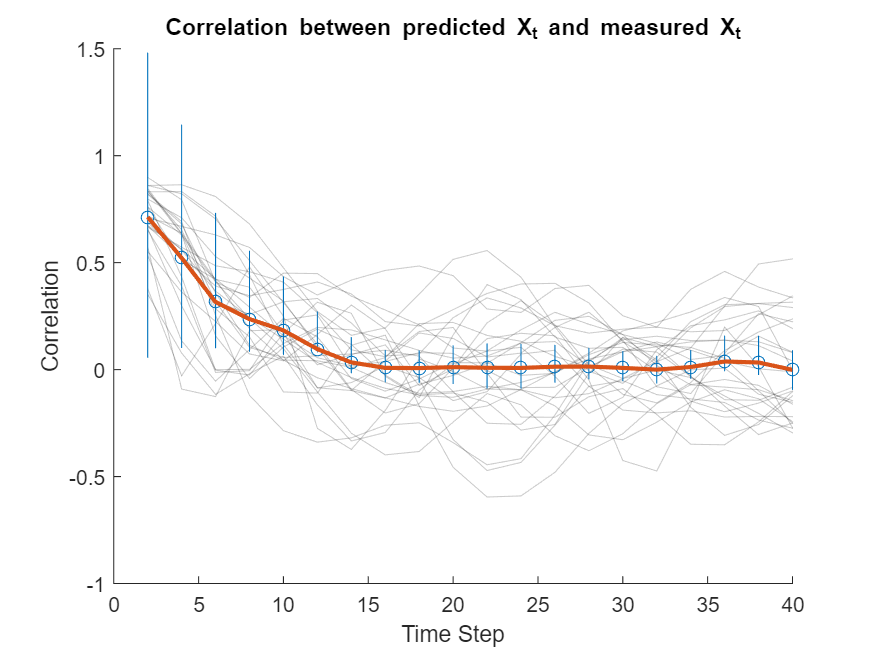

% Testing different predictive time window
% time_window = 5;
% time_dynamics = zeros(r, time_window);
% total_chunk_num = floor(size(data,2)/time_window);
% Xdmd = zeros(size(data,1), total_chunk_num*time_window);
% t = (0:time_window-1)*dt; % time vector
% for j = 1:total_chunk_num
%     x1 = data_truncated(:, (j-1)*time_window + 1);
%     b = Phi\x1;
%     for iter = 1:length(t)
%         time_dynamics(:,iter) = (b.*exp(omega*t(iter)));
%     end
%     Xdmd(:,((j-1)*time_window + 1):j*time_window) = Phi * time_dynamics;
% end 
% corr_time = corrcoef([real(Xdmd),data_truncated]);
% plot(1:234, diag(corr_time(1:234,236:end)))
% ylim([-0.6,0.8])
% title("Predictive Timewindow 5 Steps (10 second)")
% Plot Stuffs
figure 
hold on 
for i = 1:27
    line = patchline((1:20)*2, correlation_with_measured_data(i,1:20),'linewidth',0.5,'edgealpha',0.2,'edgecolor','k');
end 
averge_correlation = mean(correlation_with_measured_data,1);
for i = 1:20
    [h , p, ci, stats] = ttest(correlation_with_measured_data(:,i));
    p_result(i) = p;
    ci_result(:,i) = ci;
    t_result(i) = stats.tstat;
end
yneg = ci_result(1,:);
ypos = ci_result(2,:);
errorbar((1:20)*2, averge_correlation(1:20), yneg, ypos, 'o')
plot((1:20)*2, averge_correlation(1:20),'LineWidth',2)
title("Correlation between predicted X_t and measured X_t")
xlabel("Time (second)")
ylabel("Correlation")
hold off

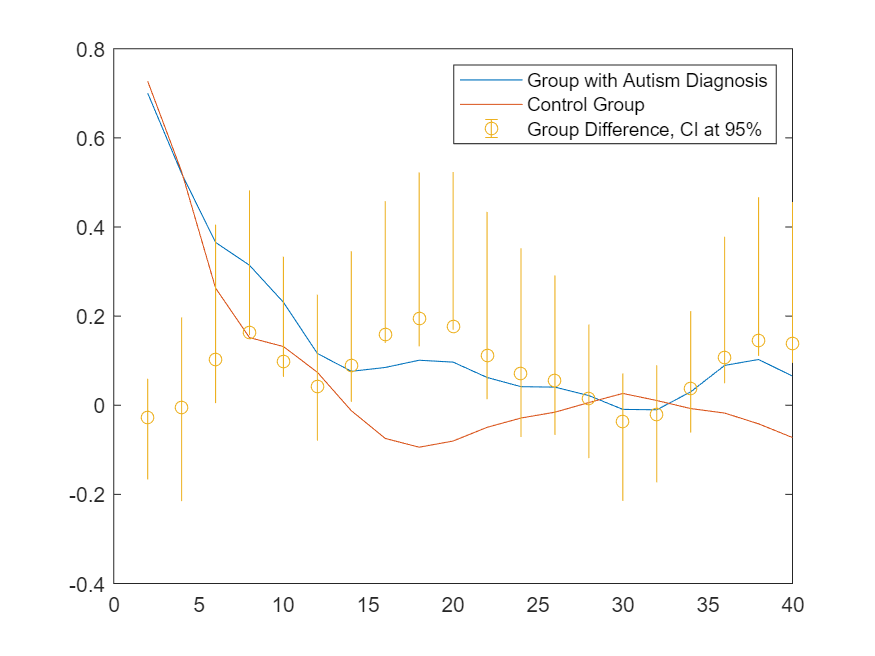

group1_cor = mean(correlation_with_measured_data(1:14,:),1);
group2_cor = mean(correlation_with_measured_data(15:end,:),1);
p_result = zeros(1,20);
ci_result = zeros(2,20);
t_result = zeros(1,20);
for i = 1:20
    [h , p, ci, stats] = ttest2(correlation_with_measured_data(1:14,i), correlation_with_measured_data(15:end,i));
    p_result(i) = p;
    ci_result(:,i) = ci;
    t_result(i) = stats.tstat;
end 
group_diff = group1_cor - group2_cor; 
figure 
plot((1:20)*2, group1_cor(1:20))
hold on 
plot((1:20)*2, group2_cor(1:20))
time_point = (1:20)*2;
yneg = ci_result(1,:);
ypos = ci_result(2,:);
errorbar(time_point, group_diff(1:20), yneg, ypos, 'o')
legend("Group with Autism Diagnosis","Control Group", "Group Difference, CI at 95%")
hold off

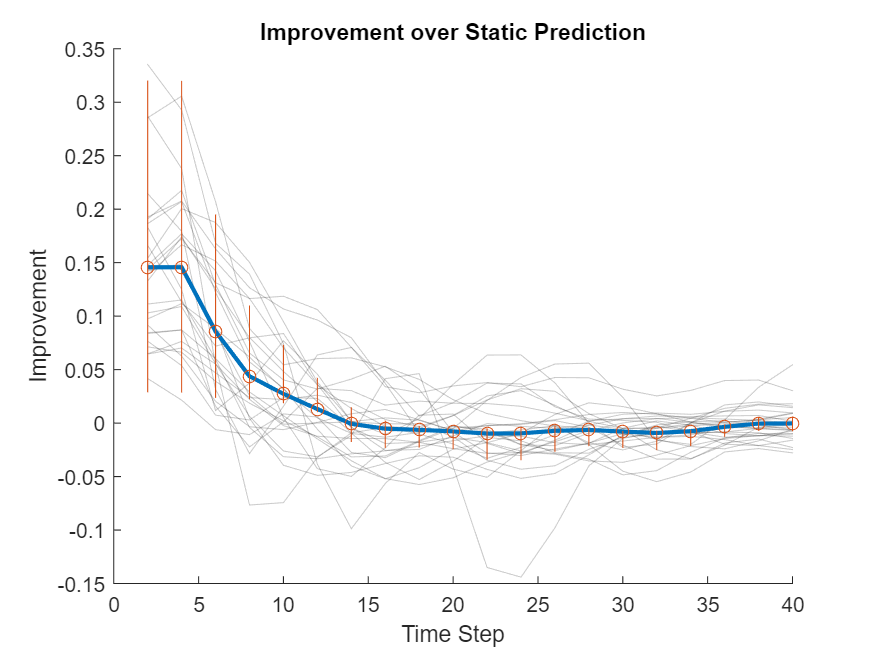

figure 
hold on 
for i = 1:N
    line = patchline((1:20)*2, improvement_over_static(i,1:20),'linewidth',0.5,'edgealpha',0.2);
end 
mean_improvement = mean(improvement_over_static);
plot((1:20)*2, mean_improvement(1:20), LineWidth=2);
for i = 1:20
    [h , p, ci, stats] = ttest(improvement_over_static(:,i));
    p_result(i) = p;
    ci_result(:,i) = ci;
    t_result(i) = stats.tstat;
end
yneg = ci_result(1,:);
ypos = ci_result(2,:);
errorbar(time_point, mean_improvement(1:20), yneg, ypos, 'o')
title("Improvement over Static Prediction")
xlabel("Time Step")
ylabel("Improvement")
hold off 

RSA

% Behavioural RSM
behav_data = readmatrix("cmu_data.csv");
behav_data = behav_data(2:end,:);
Age_matrix = zeros(N,N);
behav_data(:,4) = (behav_data(:,4) - min(behav_data(:,4)))./max(behav_data(:,4));
for i = 1:N
    for  j = 1:N
        Age_matrix(i,j) = abs(behav_data(i,4) - behav_data(j,4));
    end 
end 
Intelligence_matrix = corrcoef(behav_data(:,7:9)');
Autism_group_matrix = [ones(14,14),zeros(14,13);zeros(13,14), ones(13,13)*1];
Autism_within_group_matrix = corrcoef(behav_data(1:14,10:17)');


% Imgaging RSA
lambda = exp(omega_result*dt); % convert continous time eigenvalue to discrete time
dominant_pattern = zeros(27, 271633, 30);
for i = 1:N
    dominant_pattern(i,:,:) = squeeze(Phi_result(i,:,1:30)) * diag(lambda(i,1:30));
end 
dominant_pattern = reshape(dominant_pattern, 27, 271633*30);
imaging_RSA = corrcoef(dominant_pattern');
imaging_RSA = real(imaging_RSA); 
imaging_RSA = imaging_RSA - diag(ones(1,27));

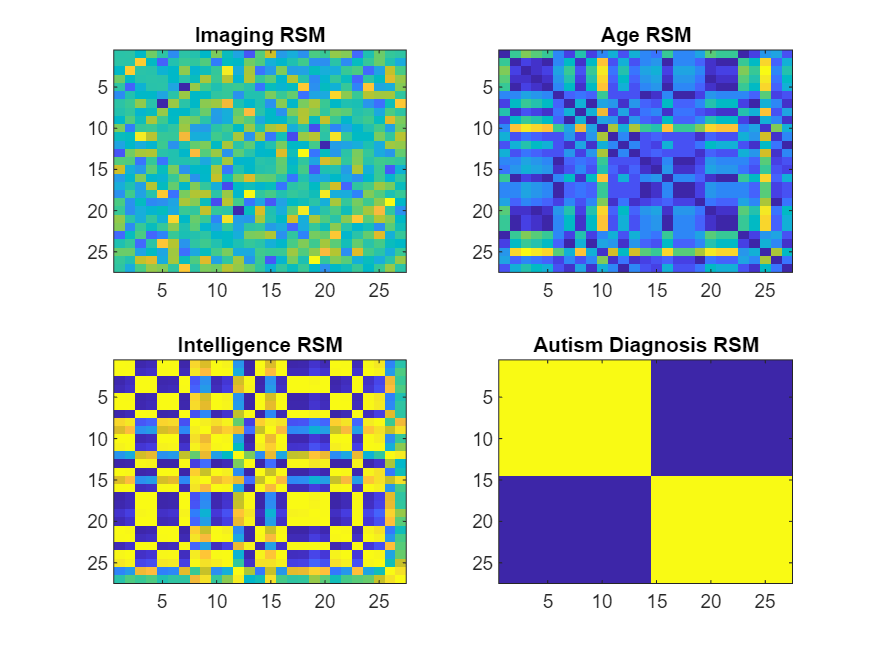

figure
subplot(2,2,1)
imagesc(imaging_RSA)
title("Imaging RSM")
subplot(2,2,2)
imagesc(Age_matrix)
title("Age RSM")
subplot(2,2,3)
imagesc(Intelligence_matrix)
title("Intelligence RSM")
subplot(2,2,4)
imagesc(Autism_group_matrix)
title("Autism Diagnosis RSM")

% Trim the matrix for correlation
Age_matrix = RSA_trim_matrix(Age_matrix);
Intelligence_matrix  = RSA_trim_matrix(Intelligence_matrix);
Autism_group_matrix = RSA_trim_matrix(Autism_group_matrix);
Autism_within_group_matrix = RSA_trim_matrix(Autism_within_group_matrix);
imaging_RSA = RSA_trim_matrix(imaging_RSA);

[correlation_result, p_values] = corr([imaging_RSA' Age_matrix', Intelligence_matrix', Autism_group_matrix' ])

correlation_result =     1.0000   -0.0203    0.0613    0.0182
   -0.0203    1.0000    0.0345    0.0447
    0.0613    0.0345    1.0000   -0.0141
    0.0182    0.0447   -0.0141    1.0000


p_values =     1.0000    0.7040    0.2518    0.7347
    0.7040    1.0000    0.5192    0.4038
    0.2518    0.5192    1.0000    0.7929
    0.7347    0.4038    0.7929    1.0000
